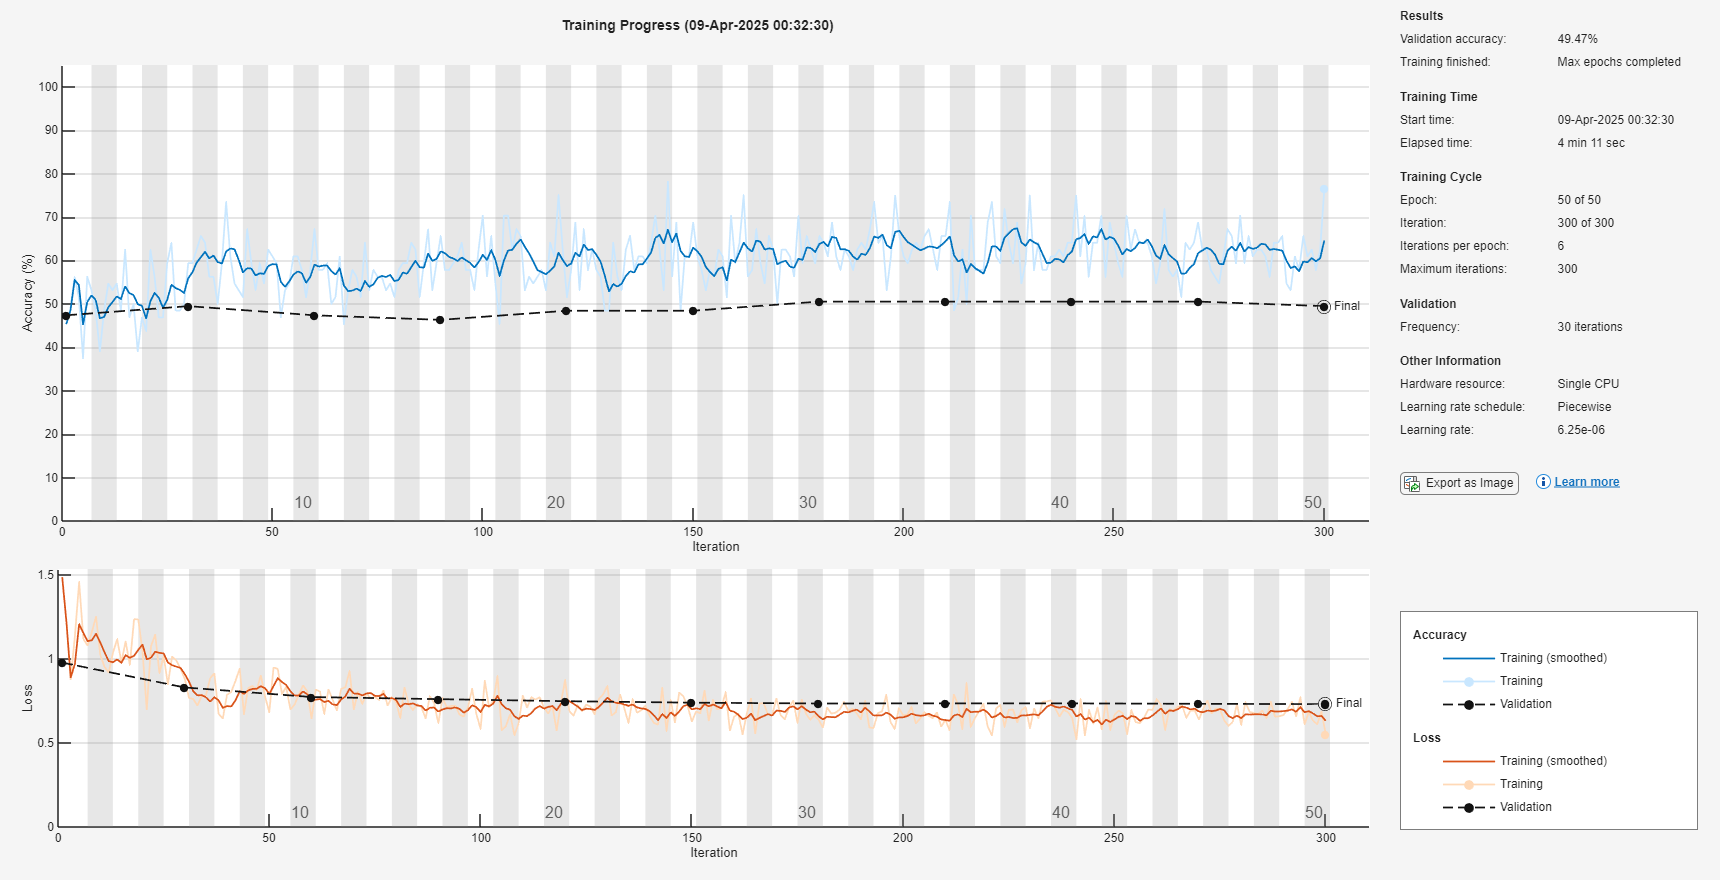

% Assuming your data is from extractFeaturesOptimized
[X, labels] = extractFeaturesOptimized(outputEntries);

% Calculate class weights to handle imbalance
numSamples = length(labels);
classCounts = [sum(~labels), sum(labels)]; % [negative, positive]
classWeights = numSamples ./ (2 * classCounts); % Inverse frequency weighting
weights = struct('false', classWeights(1), 'true', classWeights(2));

% Split data: 70% train, 15% validation, 15% test
rng('default'); % For reproducibility
cv = cvpartition(labels, 'Holdout', 0.3); % 30% for val+test
idxTrain = training(cv);
idxValTest = test(cv);

XTrain = X(:,:,:,idxTrain);
YTrain = labels(idxTrain);
XValTest = X(:,:,:,idxValTest);
YValTest = labels(idxValTest);

% Further split val+test into validation and test (50-50 split of 30%)
cv2 = cvpartition(YValTest, 'Holdout', 0.5);
idxVal = training(cv2);
idxTest = test(cv2);

XVal = XValTest(:,:,:,idxVal);
YVal = YValTest(idxVal);
XTest = XValTest(:,:,:,idxTest);
YTest = YValTest(idxTest);

% Define the CNN layers with explicit classes
% Define the CNN layers with corrections, using 4 input channels
% Define a smaller CNN architecture for 635 entries
layers = [
    % Input layer for 4 channels (128x128x4)
    imageInputLayer([128 128 1], 'Name', 'input', 'Normalization','none')
    
    % First Convolutional Block (16 filters instead of 32)
    convolution2dLayer(3, 8, 'Padding', 'same', 'Name', 'conv1')
    batchNormalizationLayer('Name', 'bn1')
    reluLayer('Name', 'relu1')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool1')
    
    % Second Convolutional Block (32 filters instead of 64)
    convolution2dLayer(3, 16, 'Padding', 'same', 'Name', 'conv2')
    batchNormalizationLayer('Name', 'bn2')
    reluLayer('Name', 'relu2')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool2')
    
    % Third Convolutional Block (64 filters instead of 128)
    convolution2dLayer(3, 32, 'Padding', 'same', 'Name', 'conv3')
    batchNormalizationLayer('Name', 'bn3')
    reluLayer('Name', 'relu3')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool3')
    
    % Fourth Convolutional Block (128 filters instead of 256)
    convolution2dLayer(3, 64, 'Padding', 'same', 'Name', 'conv4')
    batchNormalizationLayer('Name', 'bn4')
    reluLayer('Name', 'relu4')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool4')
    
    % Remove the fifth convolutional block to reduce complexity
    
    % Flatten layer
    flattenLayer('Name', 'flatten')
    
    % First Fully Connected Layer (512 units instead of 1024)
    fullyConnectedLayer(256, 'Name', 'fc1')
    reluLayer('Name', 'relu5')
    dropoutLayer(0.3, 'Name', 'drop1') % Reduced dropout rate
    
    % Second Fully Connected Layer (128 units instead of 512)
    fullyConnectedLayer(128, 'Name', 'fc2')
    reluLayer('Name', 'relu6')
    dropoutLayer(0.3, 'Name', 'drop2')
    
    % Remove the third fully connected layer (16 units)
    
    % Output Layer (2 units for binary classification)
    fullyConnectedLayer(2, 'Name', 'fc3')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'output', ...
        'Classes', categorical([false true]), ...
        'ClassWeights', [weights.false weights.true])
];

options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.0001, ...
    'MaxEpochs', 50, ...
    'MiniBatchSize', 64, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.5, ...
    'LearnRateDropPeriod', 10, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XVal, categorical(YVal)}, ...
    'ValidationFrequency', 30, ...
    'ValidationPatience', 5, ... % Stop if validation loss doesn't improve for 5 checks
    'Verbose', false, ...
    'Plots', 'training-progress', ...
    'L2Regularization', 0.01);

% Train the network
net = trainNetwork(XTrain, categorical(YTrain), layers, options);


% Evaluate on test set
YPred = classify(net, XTest);
accuracy = mean(YPred == categorical(YTest));
confusionMat = confusionmat(categorical(YTest), YPred);

% Display results
fprintf('Test Set Accuracy: %.2f%%\n', accuracy * 100);

Test Set Accuracy: 60.00%


disp('Confusion Matrix:');

Confusion Matrix:


disp(confusionMat);

    39    13
    25    18




% Calculate additional metrics
tp = confusionMat(2,2); % True positives
tn = confusionMat(1,1); % True negatives
fp = confusionMat(1,2); % False positives
fn = confusionMat(2,1); % False negatives
precision = tp / (tp + fp);
recall = tp / (tp + fn);
f1 = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f\n', precision);

Precision: 0.58


fprintf('Recall: %.2f\n', recall);

Recall: 0.42


fprintf('F1 Score: %.2f\n', f1);

F1 Score: 0.49


function [X, labels] = extractFeaturesOptimized(entries)
    numEntries = length(entries);
    height = 128;
    width = 128;
    numChannels = 1; % Only delta signal

    % Pre-allocate with single precision
    X = zeros(height, width, numChannels, numEntries, 'single');
    labels = false(numEntries, 1); % Temporary cell array for string labels

    for i = 1:numEntries
        X(:, :, 1, i) = entries{i}.delta; % Only use delta signal

        % Convert seizure label to string
        labels(i) = entries{i}.seizure;
    end
end
